# Growth rates of the Hamiltonian fluid closure of the 1.5D Vlasov-Maxwell equations

The dispersion relation $\omega(k)=\omega_p X(c k/\omega_p) $is given by the roots of the polynomial

$X^5+\kappa \tau_0 X^4 - X^3 (1+\kappa^2+ \beta^2\kappa^2)- X^2  \kappa  \tau_0(1+\kappa^2)+ X \kappa^2   (\beta^2(1+\kappa^2)-\tau_2)-\kappa^3 \tau_0\tau_2=0,$ where $\kappa = c k/\omega_p.$

The coefficients $(\beta, \tau_0)$ define the Hamiltonian closure with the relations $\tau_0=\frac{4(m \rho_0 T_{02})^{1/3}}{3mc}\lambda$ and $\beta=\frac{3\alpha^2 T_{02}}{m^2c^2T_{20}}$. The parameter $\tau_2$ is the transverse temperature (rescaled by $m c^2$). In what follows we denote by $a_2$  the ratio between the transverse and parallel temperatures, i.e., $a_2=\frac{T_{20}}{T_{02}}$. 

- *Reference:* C. Chandre and B.A. Shadwick, Hamiltonian fluid reductions of the 1.5D Vlasov-Maxwell equations (2021)

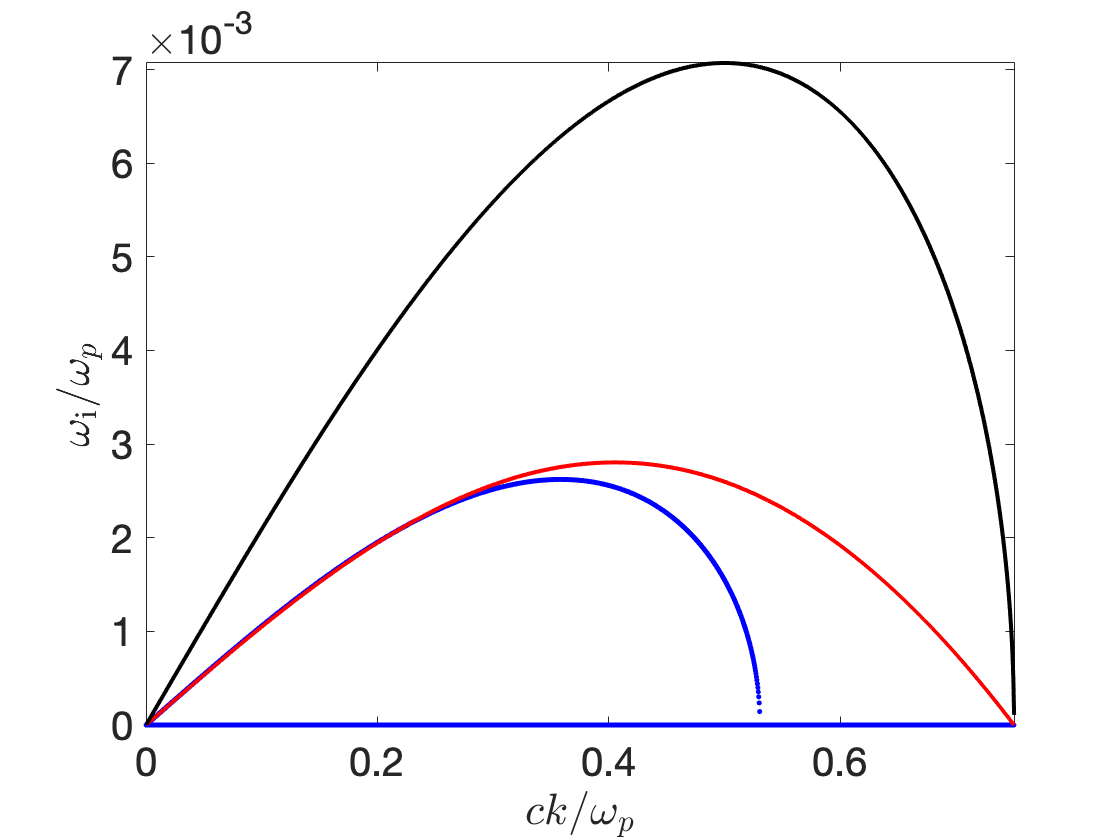

tau2 = 0.00125;
a2 = 1.5625;

beta = 1.05;
tau0 = 0.08;

beta = beta*sqrt(tau2);
tau0 = tau0*sqrt(tau2);

Nk = 5000;
kmax = sqrt(a2-1);
sz = sqrt(tau2/a2);
kappa = linspace(1/Nk, 2, Nk).';
polyy = [ones(Nk, 1) kappa*tau0 -(1+kappa.^2+beta^2*kappa.^2)...
        -kappa*tau0.*(1+kappa.^2) kappa.^2.*(beta^2*(1+kappa.^2)-tau2) -kappa.^3*tau0*tau2];
hamval = zeros(length(kappa), 5);
kinval = zeros(length(kappa), 1);
for it = 1:length(kappa)
    hamval(it, 1:5) = roots(polyy(it, :)); 
    kinval(it) = kappa(it) * fzero(@(u) -1-u^2+(a2-1)/kappa(it)^2+a2/kappa(it)^2*u/sz*sqrt(pi/2)*exp(u^2/(2*sz^2))*(erf(u/sqrt(2)/sz)-1), 0);
end
bv = 1+kappa.^2+tau2/a2*kappa.^2;
cv = kappa.^2.*(kappa.^2*tau2/a2+tau2/a2-tau2);
gauval1 = sqrt((bv-sqrt(bv.^2-4*cv))/2);
gauval2 = sqrt((bv+sqrt(bv.^2-4*cv))/2);

figure
xlabel('$c k / \omega_p$', 'Interpreter', 'latex', 'FontSize', 24)
ylabel('$\omega_{\rm i}/\omega_p$', 'FontSize', 24, 'Interpreter', 'latex')
set(gca, 'box', 'on', 'FontSize', 20)
hold on
plot(kappa, imag(hamval), 'b.');
plot(kappa, kinval, 'r', 'LineWidth', 2);
plot(kappa, imag(gauval1), 'k', 'LineWidth', 2);
xlim([0 kmax])
ylim([0 max(imag(gauval1(:)))])
hold off

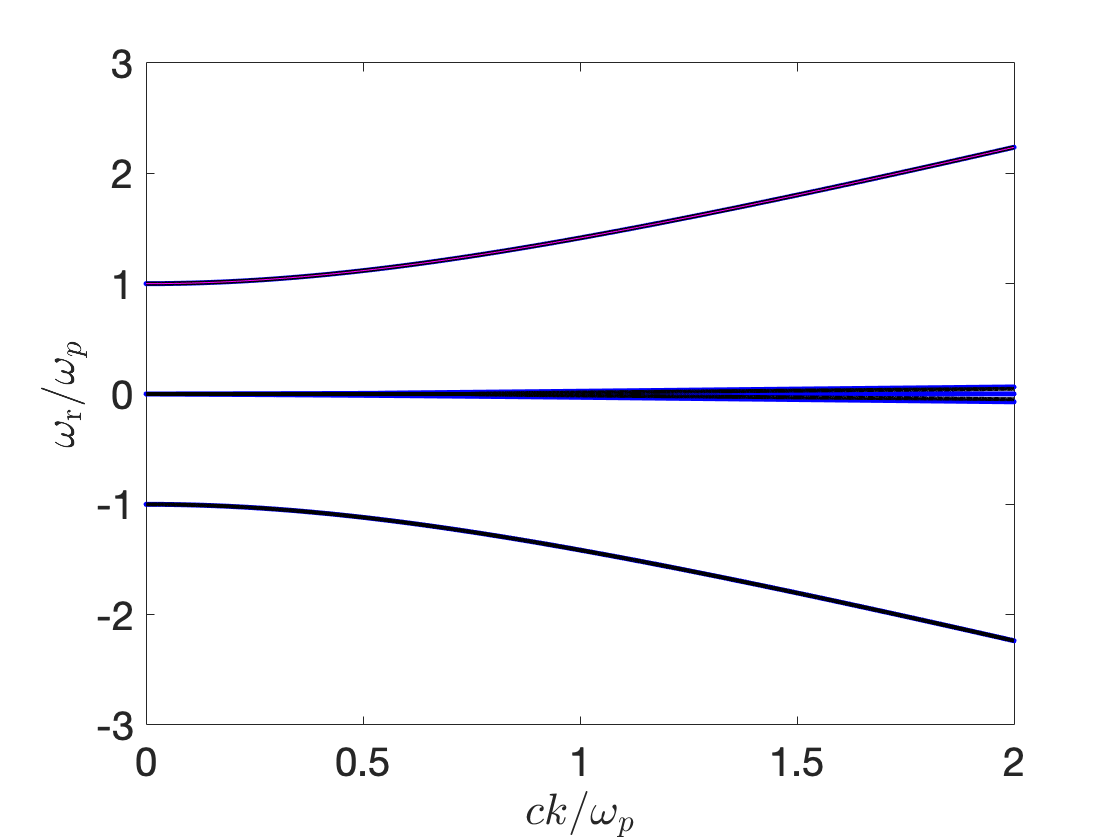


figure
xlabel('$c k / \omega_p$', 'Interpreter', 'latex', 'FontSize', 24)
ylabel('$\omega_{\mathrm r}/\omega_p$', 'FontSize', 24, 'Interpreter', 'latex')
set(gca, 'box', 'on', 'FontSize', 20)
hold on
plot(kappa, real(hamval), 'b.');
plot(kappa, real(gauval1), 'k', 'LineWidth', 2);
plot(kappa, -real(gauval1), 'k', 'LineWidth', 2);
plot(kappa, real(gauval2), 'k', 'LineWidth', 2);
plot(kappa, -real(gauval2), 'k', 'LineWidth', 2);
plot(kappa, sqrt(1+kappa.^2), 'm')

## Set of $(\beta,\tau_0)$for which the small-$\kappa$modes are unstable

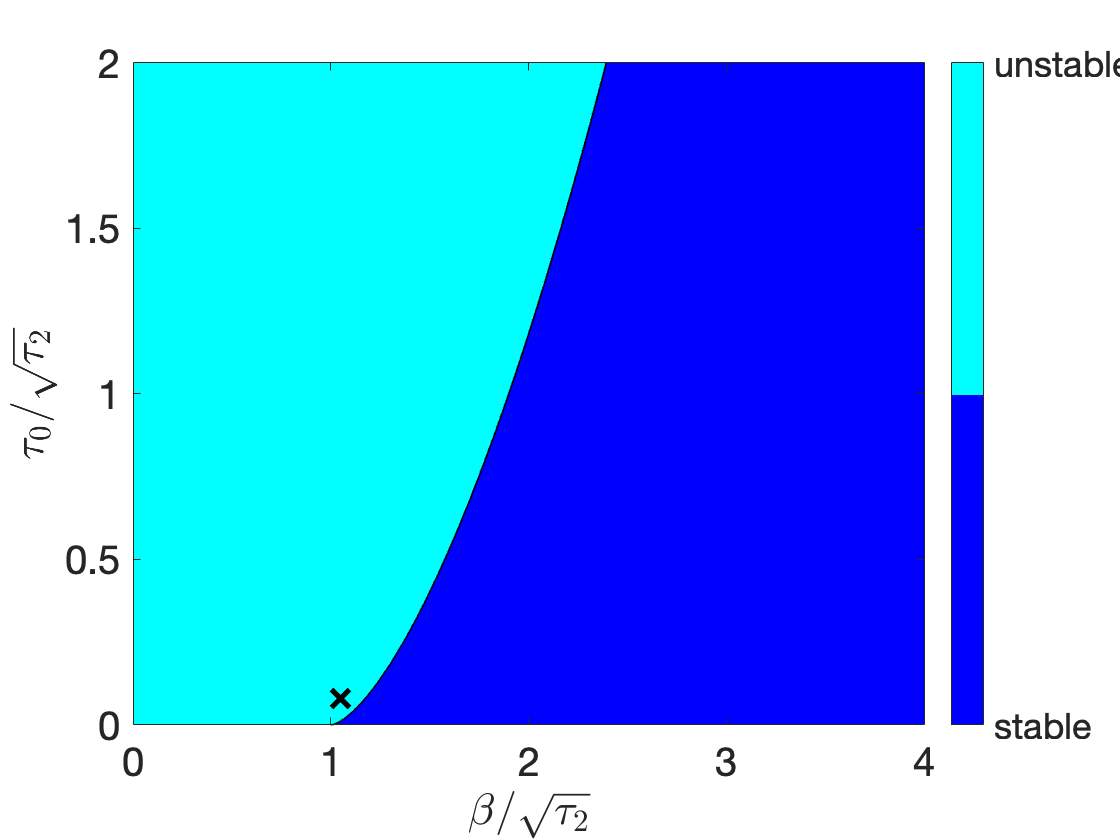

Nb = 1024;
Nt = 1024;
b = linspace(0, 4, Nb);
t = linspace(0, 2, Nt);
[B, T] = meshgrid(b, t);
Delt = 4*(B.^2-1).^3+T.^2.*(B.^4-20*B.^2-8)-4*T.^4;
St = zeros(size(Delt));
St(Delt>0) = 0;
St(Delt<0) = 1;
cmap = jet(2);
figure, contourf(B,T,St)
colormap(cmap);
xlim([min(b), max(b)])
ylim([min(t), max(t)])
c = colorbar;
set(c, 'XTick', [0, 1], 'XtickLabel', {'stable', 'unstable'})
xlabel('$\beta/\sqrt{\tau_2}$', 'Interpreter', 'latex', 'FontSize', 24);
ylabel('$\tau_0/\sqrt{\tau_2}$', 'Interpreter', 'latex', 'FontSize', 24);
set(gca, 'box', 'on', 'FontSize', 20)
hold on
plot(beta/sqrt(tau2),tau0/sqrt(tau2), 'kx', 'MarkerSize', 10, 'LineWidth', 3);

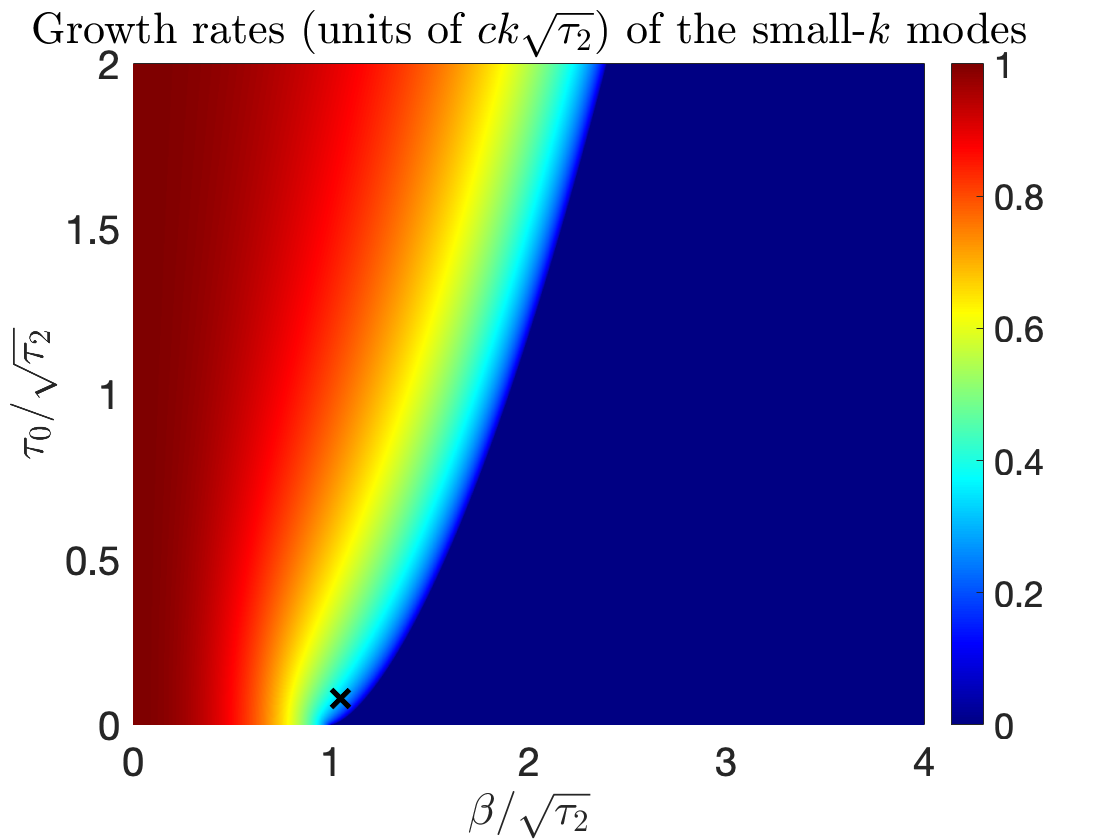


sq = sqrt(-Delt);
r = -T/3+(1+1i*sqrt(3))/6*(9/2*(2+B.^2).*T+T.^3+1.5*sqrt(3)*sq).^(1/3)+(1-1i*sqrt(3))*(-3+3*B.^2+T.^2)/3/2^(2/3)./(9*(B.^2+2).*T+2*T.^3+3*sqrt(3)*sq).^(1/3);
r(Delt>0) = NaN;
figure, pcolor(B,T,imag(r));
colormap("jet")
colorbar
shading flat
title('Growth rates (units of $c k \sqrt{\tau_2}$) of the small-$k$ modes', 'Interpreter', 'latex')
xlabel('$\beta/\sqrt{\tau_2}$', 'Interpreter', 'latex', 'FontSize', 24);
ylabel('$\tau_0/\sqrt{\tau_2}$', 'Interpreter', 'latex', 'FontSize', 24);
set(gca, 'box', 'on', 'FontSize', 20)
hold on
plot(beta/sqrt(tau2),tau0/sqrt(tau2), 'kx', 'MarkerSize', 10, 'LineWidth', 3);